# Make Distance Matrix

% load processed data
load('structureInfoTableOh2014Sorted.mat')
load('connectionMatrixOhP005_sorted.mat')
load('sortIndex.mat')

% load raw distance matrix data
oh2014SupTable4 = importdata("Oh2014SupTable4.xlsx");

% extract only ipsi
ipsiTag = contains(oh2014SupTable4.textdata(:,1),"ipsi");
ipsiDistanceMatrix = oh2014SupTable4.data(ipsiTag(2:end),ipsiTag(2:end));
ipsiRegionNameList = oh2014SupTable4.textdata(ipsiTag,1);

ipsiAcronymList = strings(size(ipsiRegionNameList));
for n = 1:295
    regionName = cell2mat(ipsiRegionNameList(n,1));
    regionName = regionName(1:length(regionName)-5);
    ipsiAcronymList(n,1) = regionName;
end

ipsiIndexList213Sorted = zeros(213,1);
for n = 1:213
    acronymName = cell2mat(table2array(structureInfoTableOh2014Sorted(n,"acronym")));
    k = find(ipsiAcronymList == acronymName);
    if isempty(k) == 0
        ipsiIndexList213Sorted(n,1) = k;
    else
        n
        acronymName
    end
end

regionDistanceMatrixOh_sorted = ipsiDistanceMatrix(ipsiIndexList213Sorted,ipsiIndexList213Sorted);

% save("regionDistanceMatrixOh_sorted.mat","regionDistanceMatrixOh_sorted")

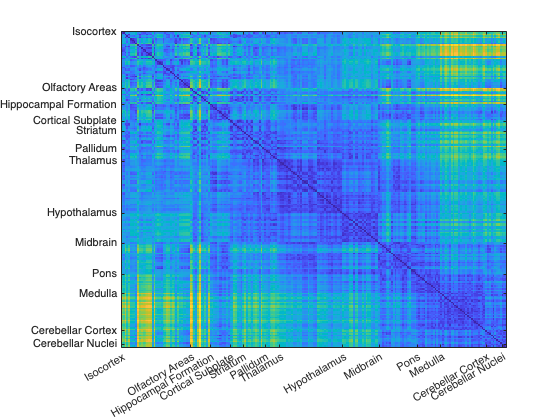

figure;
imagesc(regionDistanceMatrixOh_sorted);
MRIndTicks = [1 39 50 61 68 80 88 123 143 164 177 202 211];
load('majorRegionNameList.mat')
xticks(MRIndTicks)
xticklabels(majorRegionNameList)
yticks(MRIndTicks)
yticklabels(majorRegionNameList)